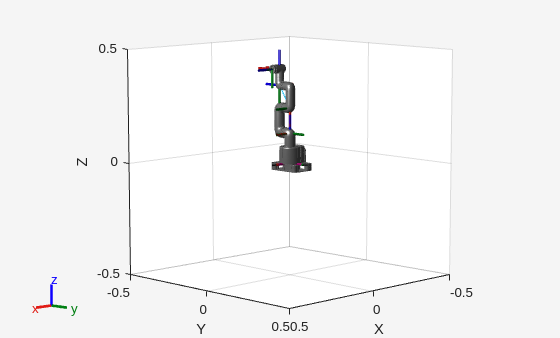

robot = importrobot('mycobot_280_arduino.urdf.xacro', 'DataFormat','row');
show(robot, [0 0 0 0 0 0]);

## Posiciones nuevas

Con los "sliders" puedes seleccionar las nuevas posiciones del robot.

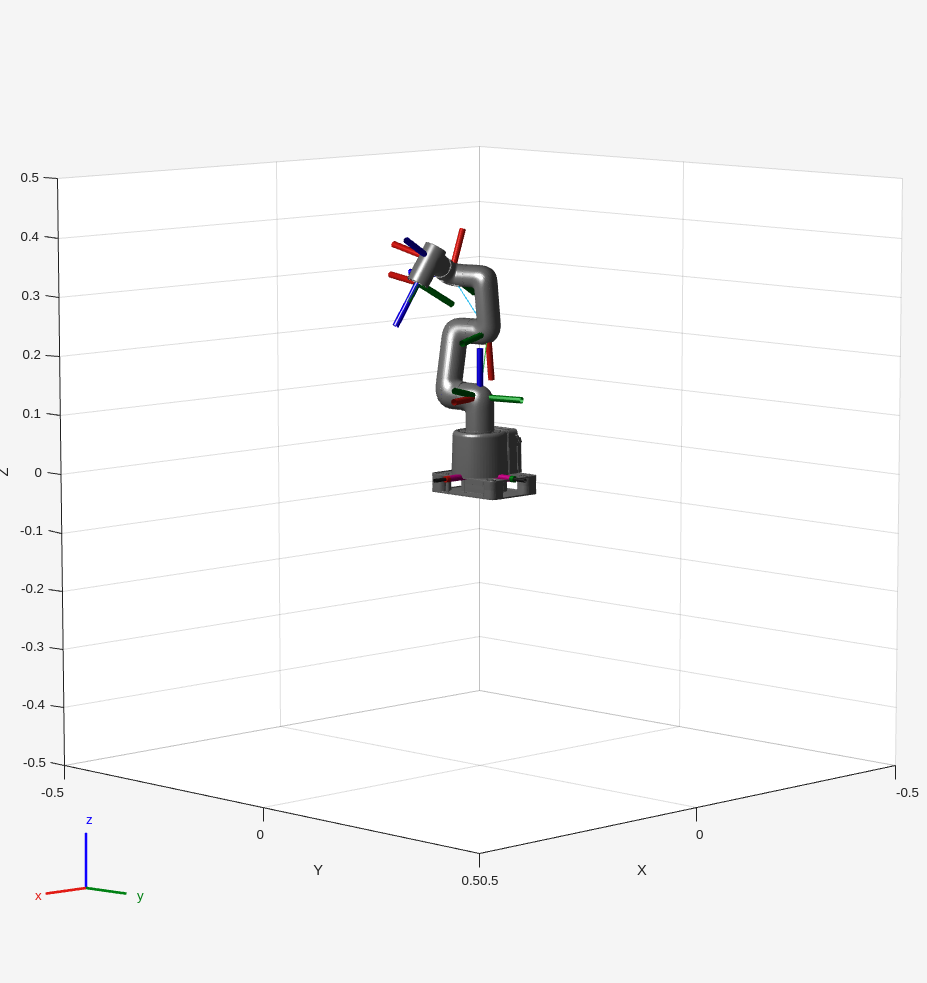

limS = 1.57;
limI = -1.57;

Q1 = 0.23;
Q2 = 0.23;
Q3 = -0.37;
Q4 = -0.97;
Q5 = -0.27;
Q6 = 0.33;

show(robot, [Q1 Q2 Q3 Q4 Q5 Q6]);

qStart = [0.63, 0.57, -0.37, -1.57, 0.63, -0.57];
qEnd = [0, 0, 0, 0, 0, 0]; % Por ejemplo, posición de reposo

% 2. Generar trayectoria (50 pasos en 3 segundos)
numPasos = 50;
t = linspace(0, 3, numPasos);
% Perfil trapezoidal para evitar tirones en los motores
[qTraj, qdTraj, qddTraj] = trapveltraj([qStart', qEnd'], numPasos);

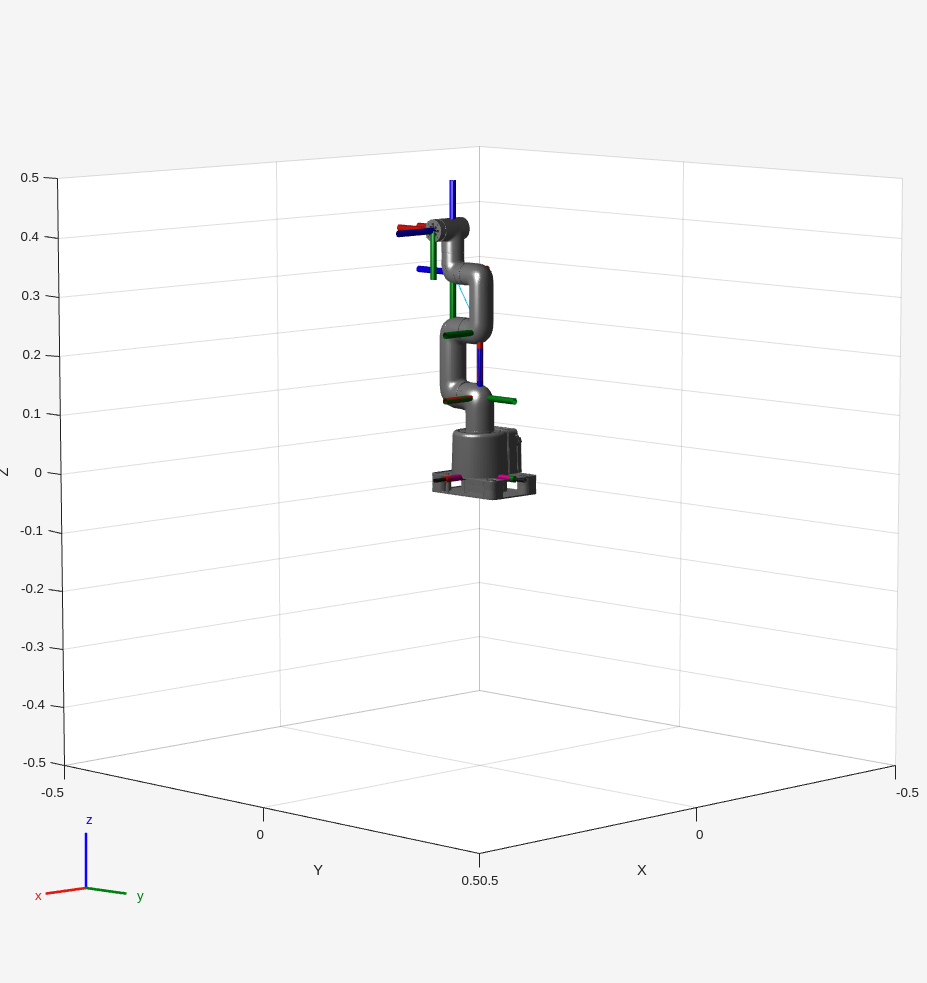


% 3. Visualizar animación
for i = 1:numPasos
    show(robot, qTraj(:,i)', 'PreservePlot', false);
    drawnow;
end

% 1. Configurar el solucionador de Cinemática Inversa
ik = inverseKinematics('RigidBodyTree', robot);
weights = [0.25 0.25 0.25 1 1 1]; % Prioridad: [orientación, posición]
initialGuess = qStart; % Usar la posición actual como semilla

% 2. Definir Waypoints cartesianos (Matrices 4x4)
% Obtenemos la posición actual como inicio
T_start = getTransform(robot, qEnd, 'joint6_flange'); % '' o tu end-effector
T_end = trvec2tform([0.1, 0.2, 0.3]) * axang2tform([0 1 0 pi/4]); % Ejemplo destino

% 3. Interpolar entre transformaciones (Trayectoria suave de matrices)
numPasos = 100;
tSamples = linspace(0, 1, numPasos);
[T_traj, ~, ~] = transformtraj(T_start, T_end, [0 1], tSamples);

% 4. Resolver IK para cada punto de la trayectoria
q_sol = zeros(numPasos, 6);
for i = 1:numPasos
    [configSol, info] = ik('joint6_flange', T_traj(:,:,i), weights, initialGuess);
    q_sol(i,:) = configSol;
    initialGuess = configSol; % Actualizar semilla para el siguiente punto
end

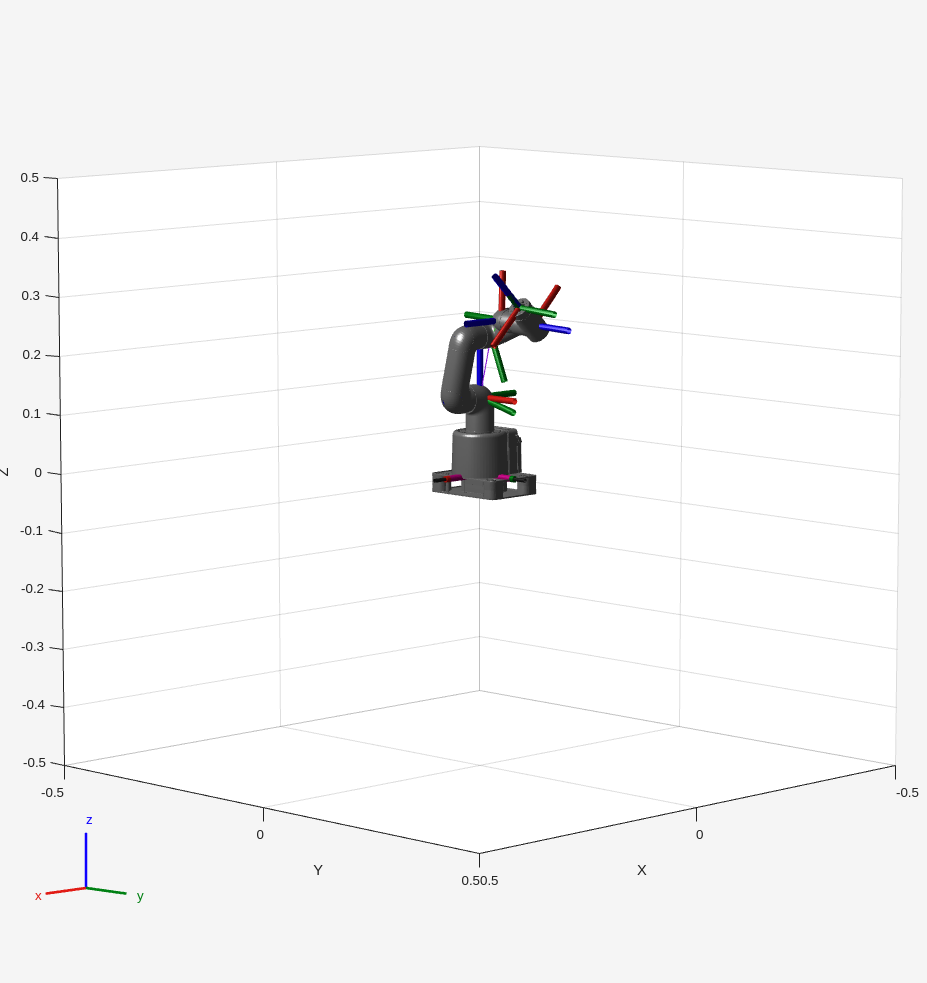


% 5. Visualizar
show(robot, q_sol(1,:)); hold on;
for i = 1:5:numPasos % Mostrar cada 5 pasos para no saturar
    show(robot, q_sol(i,:), 'PreservePlot', false);
    drawnow;
end